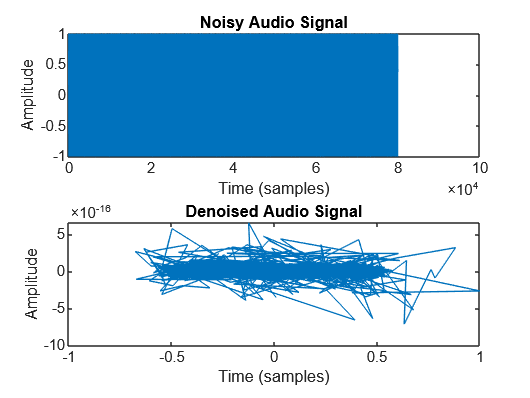

clc; clear; close all;

[noisy_signal, fs] = audioread('noisy_audio.wav');  
frame_size = 1024; 
hop_size = frame_size / 2;
win = hamming(frame_size, 'periodic');  

[stft_matrix, f, t] = stft(noisy_signal, fs, 'Window', win, 'OverlapLength', hop_size, 'FFTLength', frame_size);

mag_stft = abs(stft_matrix);
phase_stft = angle(stft_matrix);

num_noise_frames = 5; 
noise_psd = mean(mag_stft(:, 1:num_noise_frames).^2, 2);  

signal_psd = mag_stft.^2;
H_wiener = signal_psd ./ (signal_psd + noise_psd + eps);  

filtered_mag_stft = H_wiener .* mag_stft;

filtered_stft = filtered_mag_stft .* exp(1j * phase_stft);
denoised_signal = istft(filtered_stft, fs, 'Window', win, 'OverlapLength', hop_size, 'FFTLength', frame_size);

% Normalize Output :
denoised_signal = denoised_signal / max(abs(denoised_signal));  

figure;
subplot(2,1,1);
plot(noisy_signal);
title('Noisy Audio Signal');
xlabel('Time (samples)');
ylabel('Amplitude');

subplot(2,1,2);
plot(denoised_signal);
title('Denoised Audio Signal');
xlabel('Time (samples)');
ylabel('Amplitude');


disp('Noise reduction completed. Processed audio saved as denoised_audio.wav');

Noise reduction completed. Processed audio saved as denoised_audio.wav
